# Graph-independent local truncations (GILT)

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

In this tutorial, we implement the tensor renormalization group (TRG) and the graph-independent local truncations (GILT) for a square lattice.

## Exercise (a): Complete the function for the TRG and the GILT for a square lattice

There is a function `TRG_GILT_Square_Ex.m` included in the same sub-directory with this script. This function is designed to perform the TRG calculations of contracting a tensor network on an exponentially large square lattice with periodic boundary conditions. If an option `GILT` is set with a positive integer, then the function also performs the GILT to optimize the bonds between the tensors.

Refer to Sec. II A of Gu2008 [[Z.-C. Gu, M. Levin, and X.-G. Wen, Phys. Rev. B **78**, 205116 (2008)](https://journals.aps.org/prb/abstract/10.1103/PhysRevB.78.205116)] for the details of the TRG on a square lattice and Secs. IV–V of Hauru2018 [[M. Hauru, C. Delcamp, and S. Mizera, Phys. Rev. B **97**, 045111 (2018)](https://journals.aps.org/prb/abstract/10.1103/PhysRevB.97.045111)] for the details of the GILT and its application to TRG (the latter called GILT-TNR).

## Tensor network representation of the partition function of the classical Ising model

We revisit the example of the classical Ising model on a square lattice, to verify our implementation of TRG and GILT-TNR.

In a previous tutorial on the corner transfer matrix renormalization group (CTMRG), we constructed a PEPS $|\psi (\beta) \rangle$ that expresses the thermal ensemble of the classical Ising model; for example, the squared norm $\langle \psi (\beta) | \psi (\beta) \rangle$ is the partition function. The PEPS has a one-site unit cell, represented by a rank-5 tensor, whose legs are all of dimension 2. Then for the computation of the partition function (or equivalently, free energy), the rank-5 tensor is contracted to its conjugate to build a reduced tensor, which is rank-4 and has legs of dimension 4.

Actually, if we are interested only in the partition function, we can have a more compact representation of the reduced tensor. Let's consider a 2-by-2 matrix sitting on a bond between two sites $m$ and $n$, whose elements are given by the Boltzmann weights with respect to the nearest-neighbor interaction between $m$ and $n$:


$$W_{\sigma_m \sigma_n} = \exp \left[\beta (-1)^{\sigma_m + \sigma_n} \right] .$$


Here $\sigma = 1 (2)$ is the index for spin-up (down) state, respectively. Then the $W$ matrix, which is Hermitian, can be decomposed into $M M^\dagger$, where $M$ is a 2-by-2 matrix with elements


$$M_{1,1} = M_{2,1} = \sqrt{\cosh \beta}, \quad M_{1,2} = -M_{2,2} = \sqrt{\sinh \beta}.$$


Then we contract four $M$'s (each of which correponds to an edge attached to a lattice site) with a tensor whose elements are defined by a Kronecker delta, to get a reduced tensor. A compact definition of the "reduced" tensor is given by


$$T_{l u d r} = \sum_{\sigma = 1,2} M_{\sigma l} M_{\sigma u} M_{\sigma d} M_{\sigma r}.$$


Refer to Sec. II A of Hauru2018 for the details.

Let's consider the temperatures around the critical temperature $T_c = 2/\ln (1+ \sqrt{2})$.

clear

% inverse of critical temperature
betac = log(1+sqrt(2))/2;

% inverse temperatures
betas = sort([(0.4:5e-3:0.5).'; betac*[1-1e-3;1;1+1e-3]],'ascend');

% free energy per site
Fexact = zeros(size(betas)); % exact (Onsager's solution)
Ftrg   = zeros(size(betas)); % bare TRG
Fgilt  = zeros(size(betas)); % GILT-TNR

% singular values
Sv_trg  = cell(size(betas));
Sv_gilt = cell(size(betas));

Nkeep = 20; % maximum bond dimension \chi
rgstep = 25; % # of TRG coarse graining steps

for itb = (1:numel(betas))
    Fexact(itb) = -(log(2)/2 + (1/2/pi)*integral(@(x) ...
        log(cosh(2*betas(itb))^2 + sinh(2*betas(itb))* ...
        sqrt(sinh(2*betas(itb))^2 + sinh(2*betas(itb))^(-2) ...
        - 2*cos(2*x))), 0,pi))/betas(itb);

    M = [0;0]+sqrt([cosh(betas(itb)),sinh(betas(itb))]);
    M(2,2) = -M(2,2);

    T = reshape(sum(M.*reshape(M,[2 1 2]).* ...
        reshape(M,[2 1 1 2]).* ...
        reshape(M,[2 1 1 1 2]),1),[2 2 2 2]);

    [Nsq,Sv_trg{itb}] = TRG_GILT_Square_Ex (T,rgstep,Nkeep,'GILT',0);
    Ftrg(itb) = -log(Nsq)/betas(itb);

    [Nsq,Sv_gilt{itb}] = TRG_GILT_Square_Ex (T,rgstep,Nkeep,'GILT',1e3);
    Fgilt(itb) = -log(Nsq)/betas(itb);
end

While the log message is suppressed since it's too long, I would suggest you to look at it. From the log message, we can see that there are more GILT iterations performed to achieve a given convergence criterion, as $\beta$ gets closer to $\beta_c$. It means that the role of GILT, which (i) removes the irrelevant contributions to the contraction result and (ii) allocates the bond spaces to more important contributions, becomes more significant near $\beta_c$.

This advantage of using the GILT-TNR in comparison to the bare TRG is quantitatively visible from the plot of the errors in free energy.

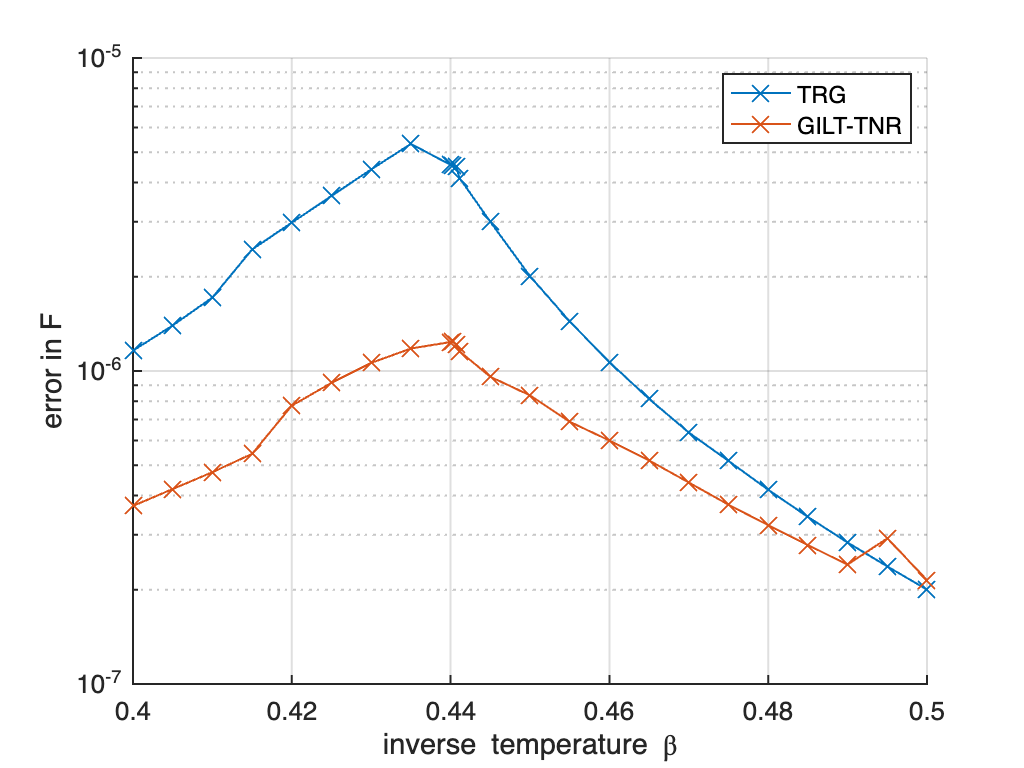

figure;
hold on;
plot(betas,abs(Ftrg-Fexact),'LineWidth',1,'Marker','x','MarkerSize',12);
plot(betas,abs(Fgilt-Fexact),'LineWidth',1,'Marker','x','MarkerSize',12);
set(gca,'YScale','log','LineWidth',1,'FontSize',13);
grid on;
xlabel('inverse temperature \beta');
ylabel('error in F');
legend({'TRG','GILT-TNR'});

Let's compare how the flows of singular values differ between the TRG and the GILT-TNR.

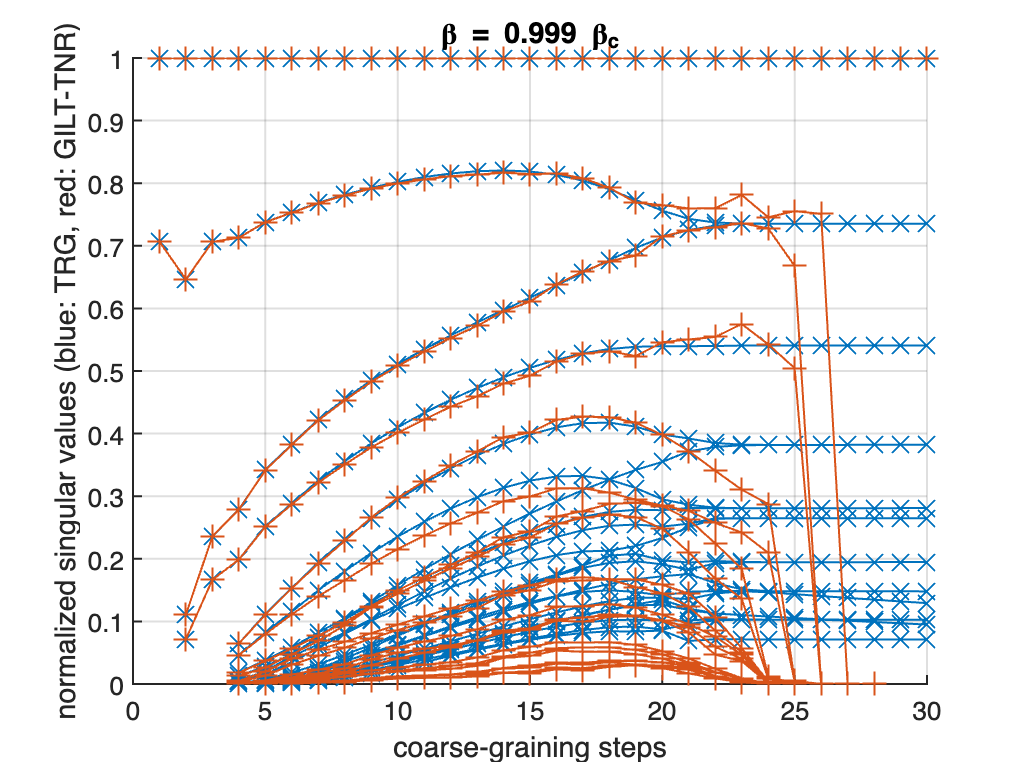

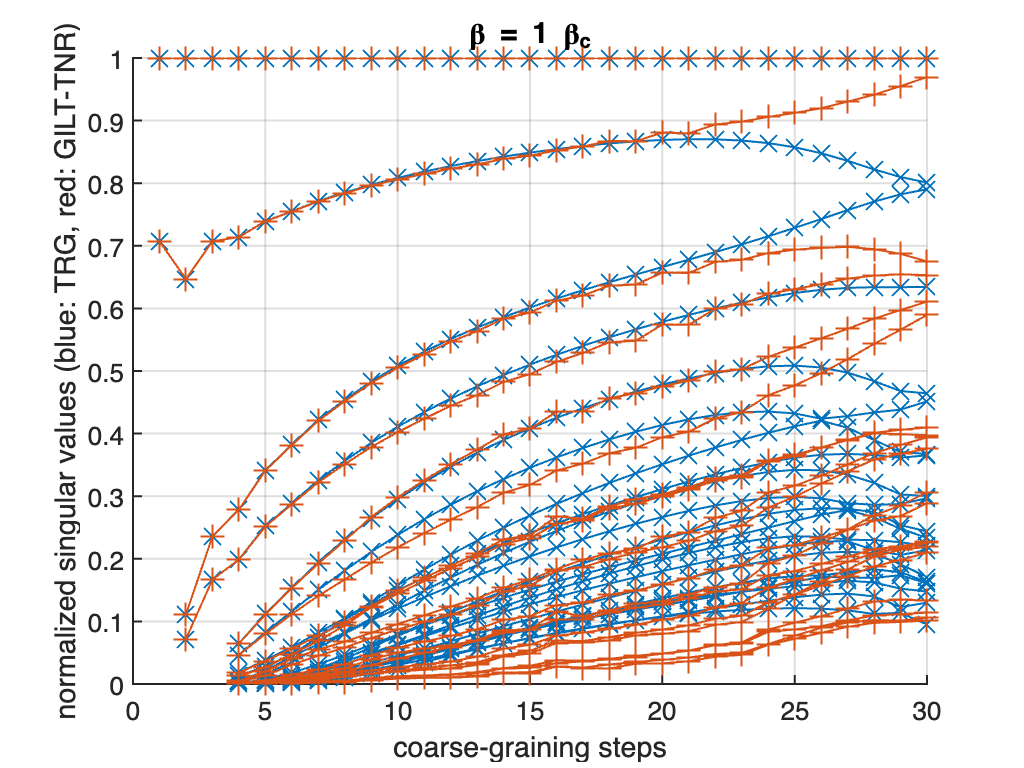

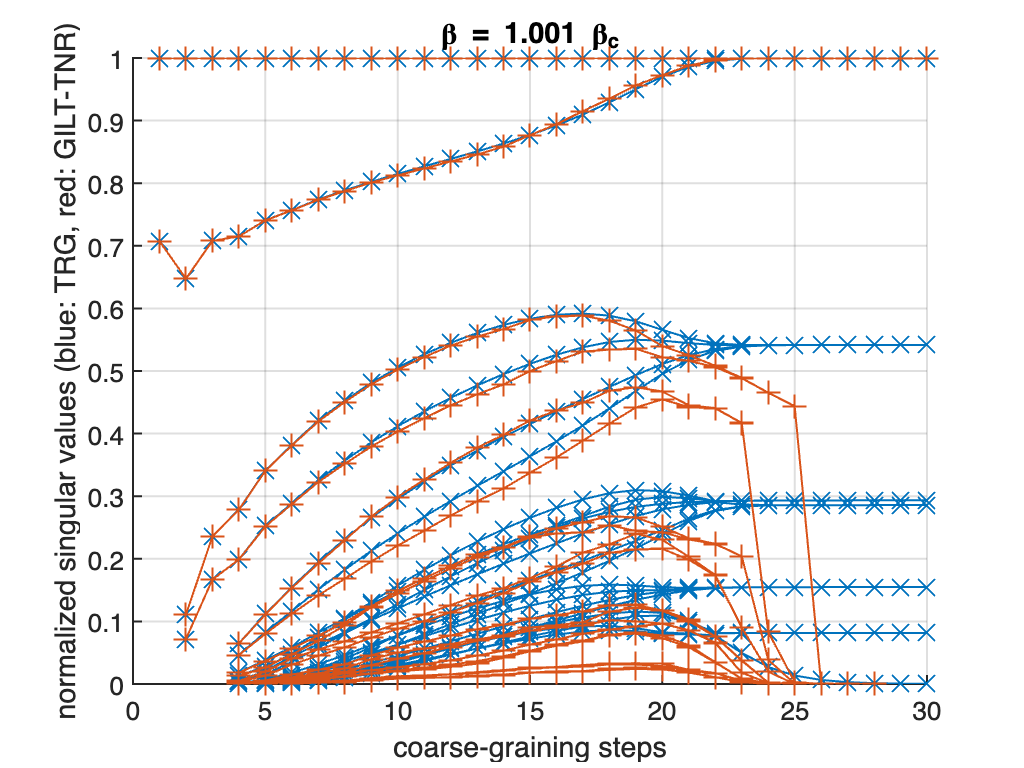

clrs = [0 .447 .741; .85 .325 .098];
ids = find(abs(betas/betac - 1) < 1.5e-3);
for itb = ids(:).'
    figure;
    hold on;
    plot((1:size(Sv_trg{itb},2)),(Sv_trg{itb}./Sv_trg{itb}(1,:)).', ...
        'LineWidth',1,'Color',clrs(1,:),'Marker','x','MarkerSize',12);
    plot((1:size(Sv_gilt{itb},2)),(Sv_gilt{itb}./Sv_gilt{itb}(1,:)).', ...
        'LineWidth',1,'Color',clrs(2,:),'Marker','+','MarkerSize',12);
    hold off;
    set(gca,'LineWidth',1,'FontSize',13);
    grid on;
    xlabel('coarse-graining steps');
    ylabel('normalized singular values (blue: TRG, red: GILT-TNR)');
    title(['\beta = ',sprintf('%.4g',betas(itb)/betac),' \beta_c']);
end

We find that, for $\beta \neq \beta_c$, the GILT-TNR results in only one (for $\beta < \beta_c$) or two (for $\beta > \beta_c$) singular values at the last coarse-graining steps, while the TRG keeps many singular values. As we can see from the error plot, those small singular values are irrelevant.

Actually, in the RG sense, the structure of the singular values at the last steps should capture the long-range behavior of the system, with all short-range features removed. For higer temperatures ($\beta < \beta_c$), the system is disordered. If we ignore short-range details, the state is similar to the infinite-temperature ($\beta = 0$) state, whose tensor network (TN) representation is very simple; all the tensors have singleton bond dimensions, since the spins are uncorrelated. So the uniquley surviving singular value at the last step of GILT-TNR for $\beta < \beta_c$ corresponds to the $\beta = 0$ fixed point with the separable TN representation.

On the other hand, for lower temperatures ($\beta > \beta_c$), the system is in a symmetry-broken phase with two possible configurations. One configuration has spin-up magnetization and the other has spin-down. Each configuration has a PEPS representation (again) with singleton dimensions. The two singular values at the last coarse-graining step of GILT-TNR for $\beta > \beta_c$ counts the two configurations.

Meanwhile, the bare TRG cannot eliminate short-range features, that remain as sub-leading singular values.

Note that, in the CTMRG, the sub-leading singular values are kept since the corner and transfer tensors are coarse-grained only towards the outside; their legs towards the unit cell should know about the short-range features.